# Example of reconstructing a continuous signal through its samples using convolution

clear; clc;

Parameters

phi = 0;
om = 1;
T = 1;

Signal

r = @(t) sin(om*t+phi) + sin(1.5*om*t+phi+pi/3);   % Continuous input function
r_kT = @(k) r(k*T);       % Samples of r

Samples used for reconstruction

k1 = -10;   % Lower bound (first sample)
k2 = 0;   % Upper bound (last sample)

Reconstruction

t_v = -10:0.01:5;             % Reconstructs the signal for t in [-10, +5]
r1_v = zeros(1,length(t_v));
for i = 1:length(t_v)
    r1_v(i) = r_recon(t_v(i), r_kT, k1, k2, T);
end

Plot

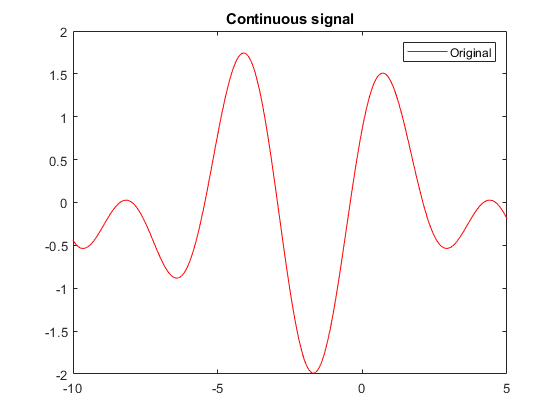

k_v = k1:1:k2;
figure;
plot(t_v, r(t_v), 'r'); hold on;
legend('Original'); title('Continuous signal');
hold off;

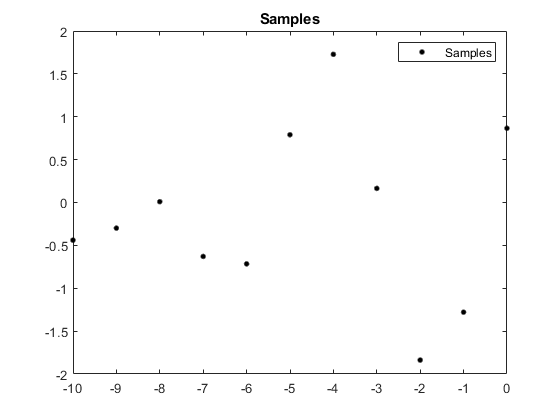


figure;
plot(k_v*T, r_kT(k_v),'.k','MarkerSize',12); hold on;
legend('Samples'); title('Samples');
hold off;

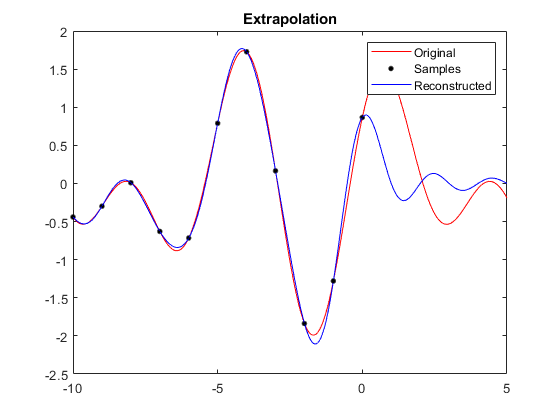


figure;
plot(t_v, r(t_v), 'r'); hold on;
plot(k_v*T, r_kT(k_v),'.k','MarkerSize',12); hold on;
plot(t_v, r1_v, 'b'); hold on;
legend('Original','Samples','Reconstructed'); title('Extrapolation');
hold off;